# Interactive MATLAB Lab 1.9: Existence and Uniqueness Explorer

In a Live Script, turn "mode" into a drop-down control. Use y0 for the unique case and a for the nonunique case.

Unique initial-value problem: y' = x+y, y(0)=y0


Solution:


$$2\,{\mathrm{e}}^{x}-x-1$$

Verification:


   1



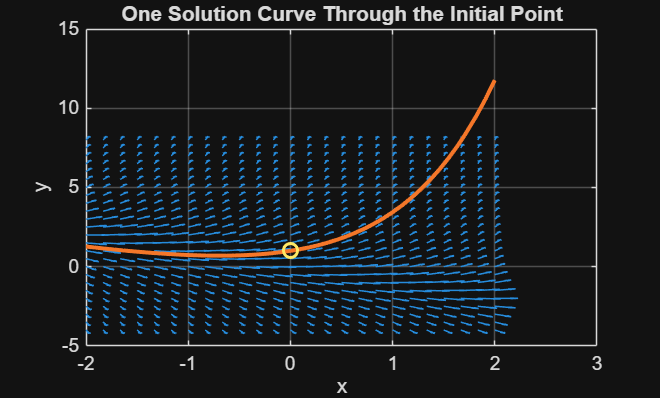

mode = "Unique IVP";   % Options: "Unique IVP", "Nonunique IVP"
y0 = 1;
a = 4;

switch mode
    case "Unique IVP"
        syms x y(x)

        ode = diff(y,x) == x + y;
        solution = dsolve(ode,y(0) == y0);

        residual = simplify(diff(solution,x) - x - solution);
        initialCheck = simplify(subs(solution,x,0) - y0);
        verified = isequal(residual,sym(0)) && isequal(initialCheck,sym(0));

        [X,Y] = meshgrid(linspace(-2,2,25),linspace(-4,8,25));
        U = ones(size(X));
        V = X + Y;
        arrowLength = sqrt(U.^2 + V.^2);
        U = U./arrowLength;
        V = V./arrowLength;

        disp("Unique initial-value problem: y' = x+y, y(0)=y0")
        disp("Solution:")
        disp(solution)
        disp("Verification:")
        disp(verified)

        figure
        quiver(X,Y,U,V,0.45)
        hold on
        fplot(solution,[-2 2],'LineWidth',2)
        plot(0,y0,'o','MarkerSize',7,'LineWidth',1.5)
        hold off
        grid on
        xlabel('x')
        ylabel('y')
        title('One Solution Curve Through the Initial Point')

    case "Nonunique IVP"
        x = linspace(0,6,500);
        equilibrium = zeros(size(x));
        delayed = zeros(size(x));

        mask = x > a;
        delayed(mask) = (x(mask)-a).^2/4;

        disp("Nonunique initial-value problem: y' = sqrt(|y|), y(0)=0")
        disp("Waiting time a: " + string(a))
        disp("The solution can remain at y=0 until x=a and then leave the equilibrium.")

        figure
        plot(x,equilibrium,'LineWidth',1.5)
        hold on
        plot(x,delayed,'LineWidth',2)
        hold off
        grid on
        xlabel('x')
        ylabel('y')
        title('Many Solutions Through the Same Initial Point')
        legend('Equilibrium solution y=0','Delayed solution','Location','best')
end